open_system('task3');
set_param('task3/y_1', 'VariableName', 'y_1')
set_param('task3/y_2', 'VariableName', 'y_2')

out = sim('task3');

x=0.01:0.01:10;
inp_1= sign(x);
inp_2 = 2 * sin(x)

inp_2 =     0.0200    0.0400    0.0600    0.0800    0.1000    0.1199    0.1399    0.1598    0.1798    0.1997    0.2196    0.2394    0.2593    0.2791    0.2989    0.3186    0.3384    0.3581    0.3777    0.3973    0.4169    0.4365    0.4560    0.4754    0.4948    0.5142    0.5335    0.5527    0.5719    0.5910    0.6101    0.6291    0.6481    0.6670    0.6858    0.7045    0.7232    0.7418    0.7604    0.7788    0.7972    0.8155    0.8337    0.8519    0.8699    0.8879    0.9058    0.9236    0.9413    0.9589


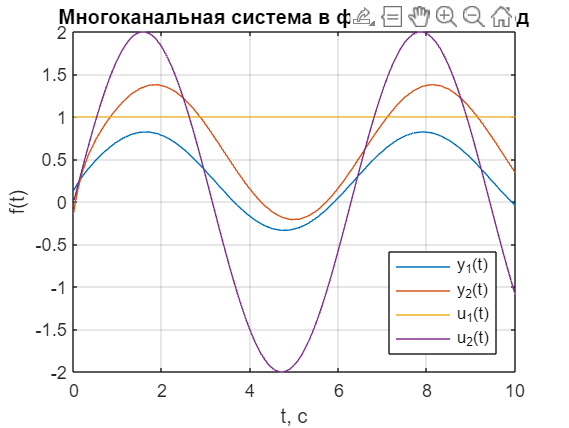

plot(out.y_1, 'DisplayName', 'y_1(t)')
hold on
plot(out.y_2, 'DisplayName', 'y_2(t)')
hold on
plot(x, inp_1,'DisplayName','u_1(t)')
hold on
plot(x, inp_2,'DisplayName','u_2(t)')
grid()
title('Многоканальная система в форме вход-выход')
legend("Position", [0.68256,0.16952,0.19289,0.24566])
ylabel('f(t)')
xlabel('t, с')
hold off